# TALLER DE PROCESADO DE IMÁGENES CON MATLAB

**MATLAB UPV Ambassadors**

**Dairon Andrés Benites Aldaz**

**    Universidad Politécnica de Valencia**

**18 de marzo de 2021**

### Visualización de imágenes con MATLAB

*En esta sección aprenderemos a visualizar las imágenes y sus canales con MATLAB.*

clc
clear

Iciervo= imread("images/ciervo.jpg")

Iciervo = 411×730×3 uint8 array
Iciervo(:,:,1) =

   197   199   199   198   199   199   199   198   198   199   200   202   201   199   199   200   200   199   198   198   199   201   201   199   200   202   204   203   201   202   202   200   197   199   201   201   199   200   203   201   200   202   203   202   202   203   204   204   207   204   202   204   205   207   206   202   203   206   208   208   207   206   208   208   202   200   202   203   204   204   205   206   208   208   203   202   207   208   205   205   207   206   206   206   206   207   209   210   210   210   210   211   206   208   208   207   206   204   205   205   206   206   208   208   208   206   205   207   207   207   206   206   207   208   210   209   209   211   211   210   207   208   212   209   212   211   213   212   210   210   210   210   209   210   208   208   206   207   205   205   207   207   208   209   208   208   208   208   209   209   209   208   209   211   211   211   211   210  

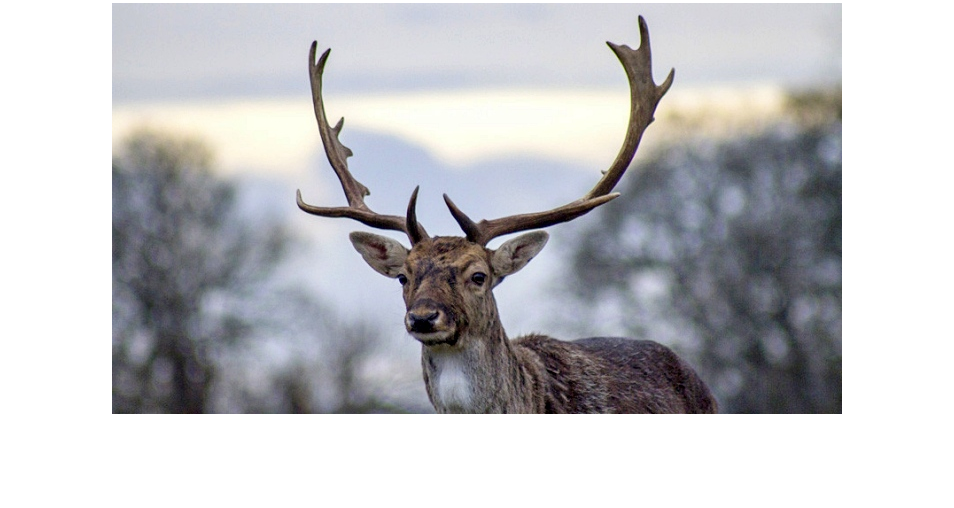

imshow(Iciervo)
title('Original Image')

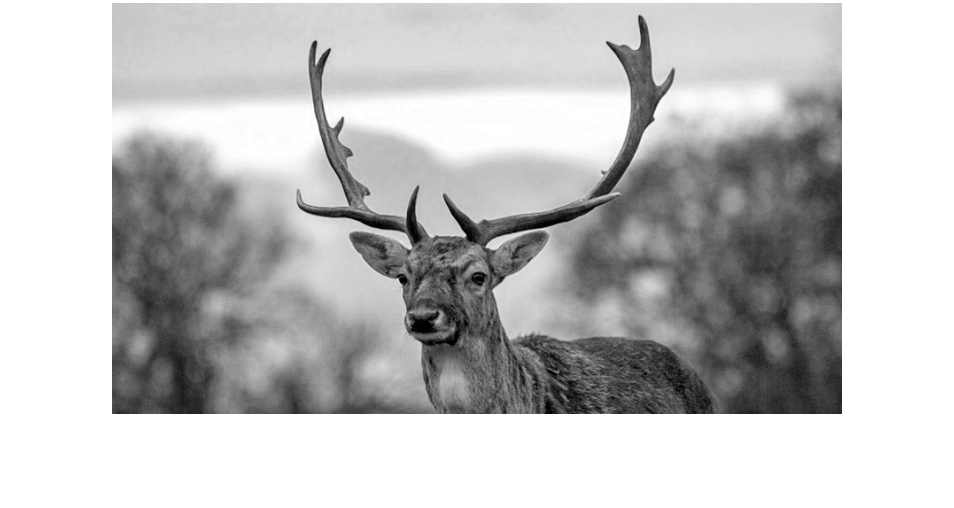

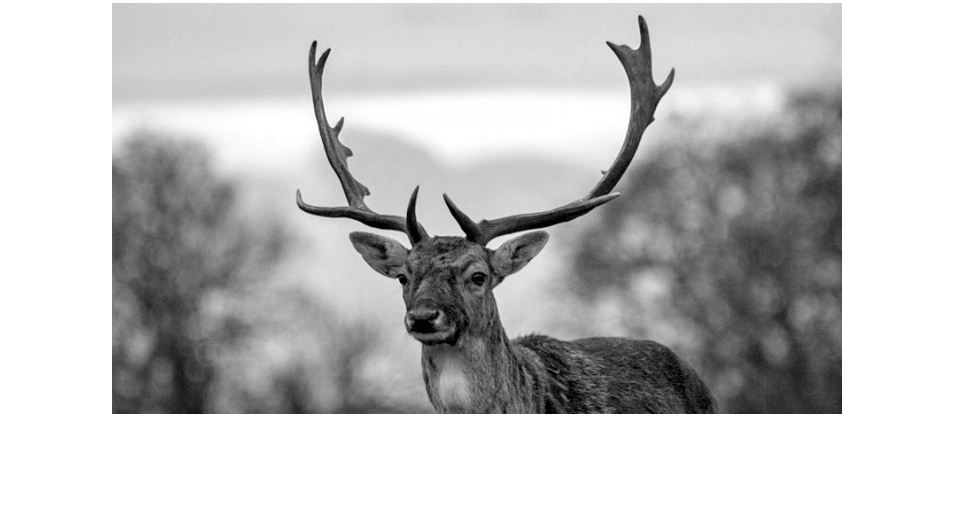

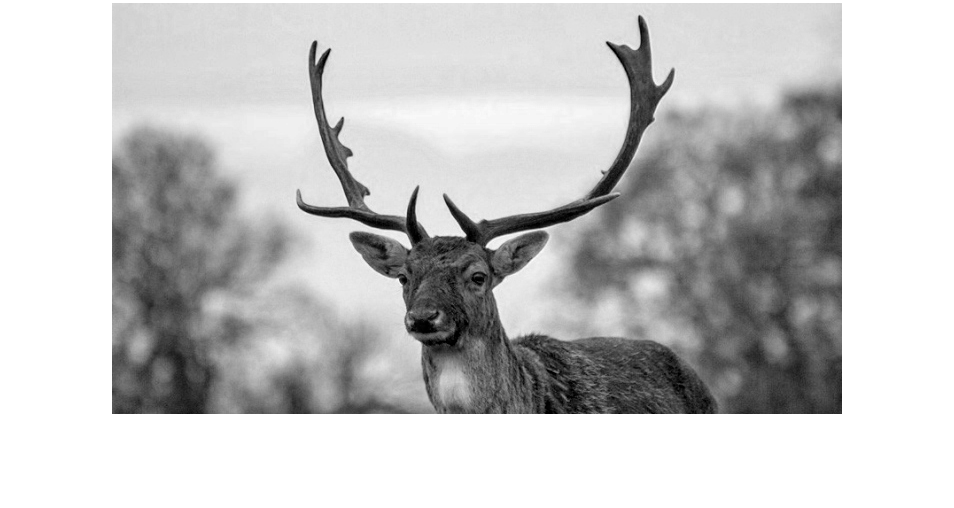


canales = {'R', 'G', 'B'};
for i = 1:size(Iciervo,3)
    figure
    imshow(Iciervo(:, :, i))
    title(canales{i})
end

### Transformación de color: RGB a escala de grises

*En esta sección aprenderemos a transformar las imágenes a color (RGB) a escala de grises.*

Iciervog = rgb2gray(Iciervo)

Iciervog = 411×730 uint8 matrix
   200   202   202   201   202   202   202   201   201   202   203   205   204   202   202   203   203   202   201   201   202   204   204   202   203   205   207   206   204   205   206   204   201   203   205   205   202   203   206   204   204   206   207   206   206   207   207   207   207   204
   203   203   202   202   202   202   202   202   202   202   203   203   202   201   201   202   203   202   202   202   202   203   203   201   204   205   207   205   203   204   205   203   204   206   207   206   204   204   206   204   200   204   206   206   207   207   206   206   209   207
   203   202   202   201   202   202   202   202   202   202   202   203   202   202   202   203   201   201   201   202   203   204   204   202   204   206   206   204   202   203   204   203   204   207   206   206   205   205   205   204   203   204   205   206   208   208   206   203   208   208
   200   200   200   201   201   201   201   201   201   201   20

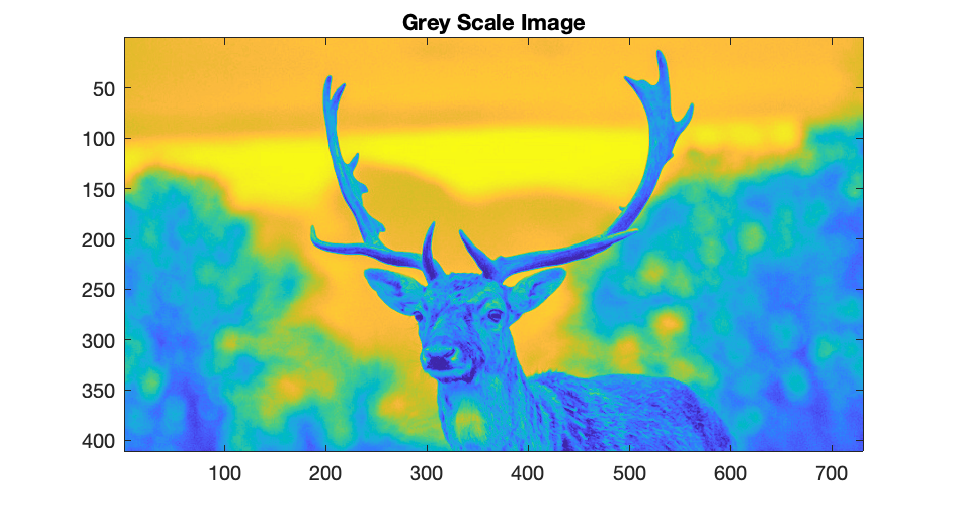

imagesc(Iciervog)
title('Grey Scale Image')

### Operaciones básicas

*En esta sección aprenderemos calcular el histograma de una imagen y algunas técnicas para realzar el brillo y el contraste.*

Ipout = imread('pout.tif')

Ipout = 291×240 uint8 matrix
   107   108   107   106    99   101   102   107   107   103   112   164   200   197   170   182   213   214   212   197   137   112   110   109   112   110   107   105   106   106   107   109   108   106   106   106    99    98    99   101    99   102   103   105   103   119   147   205   204   209
   109   106   108   107   103   102   103   110   113   108   128   182   210   210   182   166   189   210   213   210   167   119   110   108   112   110   106   106   107   107   105   107   106   107   108   107   106   102    95   103   106   108   121   120   109   128   161   208   207   212
   107   106   110   110   106   107   107   120   133   133   125   151   181   189   175   151   159   204   210   212   189   137   119   107   110   110   107   108   108   107   106   106   106   105   106   108   107   105    98   103   128   150   164   137   121   133   169   208   210   215
   106   107   108   108   108   108   108   114   126   146   133  

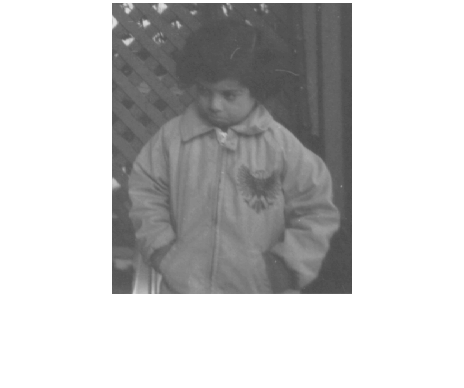

imshow(Ipout)
title('imagen original')

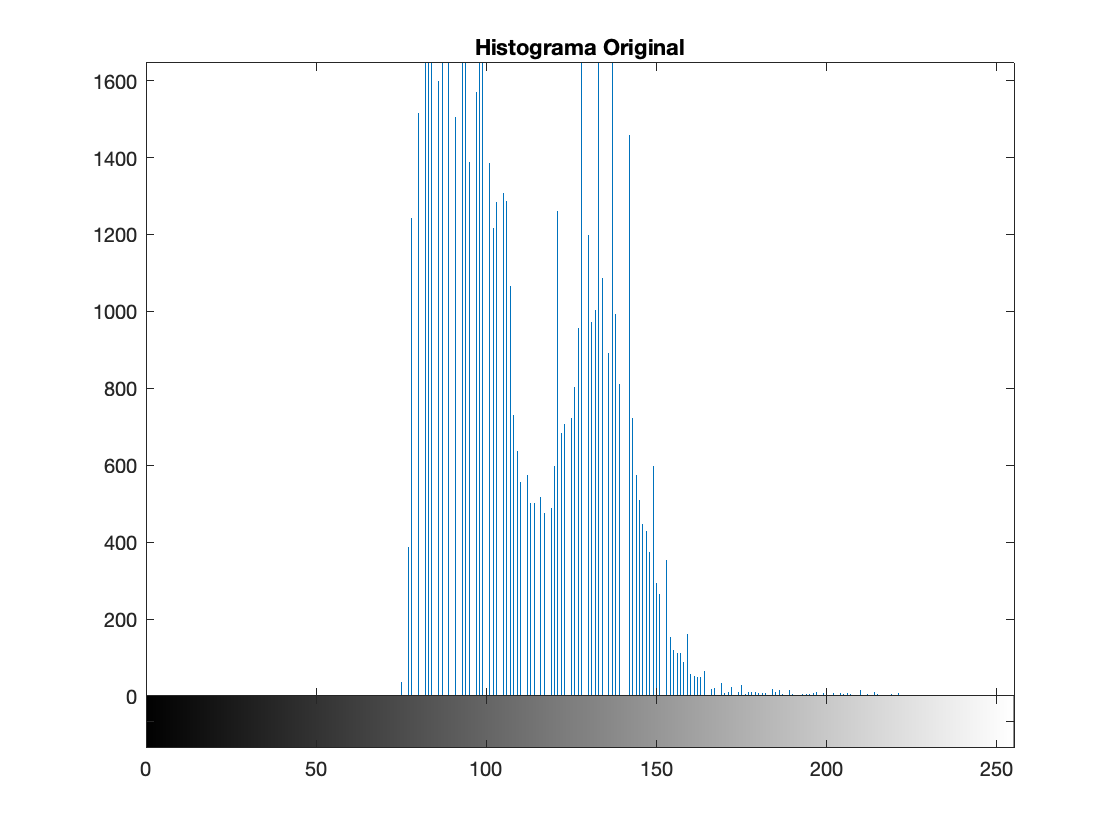

figure
imhist(Ipout)
title('Histograma Original')

Modificación del brillo y del contraste:

Luminosidad y contraste: modificación lineal

Ecualización de histograma

### Filtros

*En esta sección aprenderemos a filtrar imágenes con diferentes tipos de filtros.*

Filtros de bordes:

Filtros especiales:

### Clasificación de tejidos 

*En esta sección aprenderemos utilizar el algoritmo de clustering k-means y lo aplicaremos sobre una imagen histológica.*